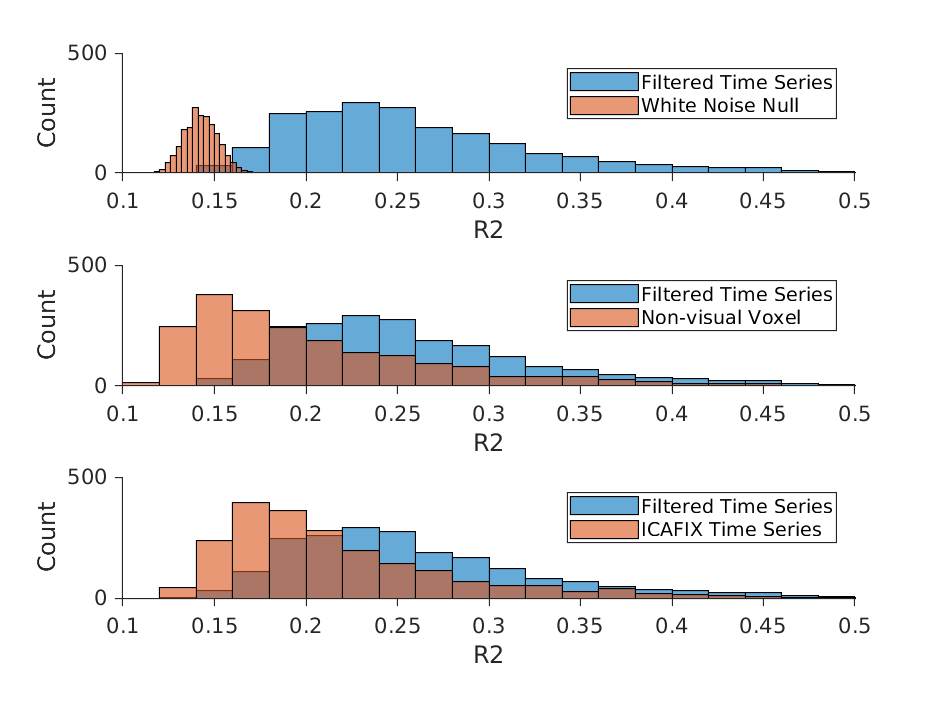

%% Compare the r-sqaure of GLM Model fits
base = '~/Data/fMRI/HERO_LZ';

figure();
load(fullfile(base, 'GLM_HERO_LZ_NeuralCoding01.mat'));
load(fullfile(base, 'GLM_Null_Gaussian.mat'));

% Compare with Null distribution
subplot(3, 1, 1);
histogram(results.R2); hold on;
histogram(resultsNull.R2); box off;

xlabel('R2')
ylabel('Count');
legend({'Filtered Time Series', 'White Noise Null'})
xlim([0.1, 0.5]); ylim([0, 500]);
set(gca,'TickDir','out');

% Compare with Non visual area
subplot(3, 1, 2);
load(fullfile(base, 'GLM_Non_Visual.mat'));
histogram(results.R2); hold on;
histogram(resultsNonVis.R2); box off;

xlabel('R2')
ylabel('Count');
legend({'Filtered Time Series', 'Non-visual Voxel'})
xlim([0.1, 0.5]); ylim([0, 500]);
set(gca,'TickDir','out');

% with/without ICAFIX
subplot(3, 1, 3);
load(fullfile(base, 'GLM_HERO_LZ_NeuralCoding01.mat'));
histogram(results.R2); hold on;
load(fullfile(base, 'GLM_HERO_LZ_NeuralCoding01_ICAFIX.mat'));
histogram(results.R2); box off;

xlabel('R2')
ylabel('Count');
legend({'Filtered Time Series', 'ICAFIX Time Series'})
xlim([0.1, 0.5]); ylim([0, 500]);
set(gca,'TickDir','out');

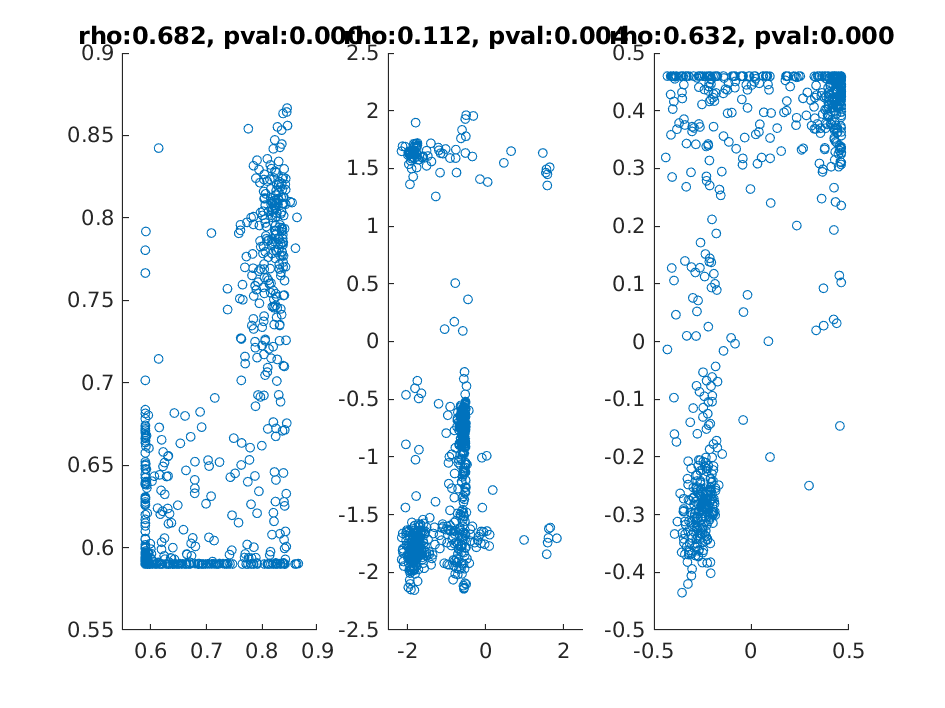

%% Compare HRF parameters across session
allPara = cell(1, 3);
rSqr = cell(1, 3);
fnBase = '~/Data/fMRI/HERO_LZ/GLM_HERO_LZ_NeuralCoding%02d.mat';
nSession = 3;

for idx = 1:nSession
    fn = sprintf(fnBase, idx);    
    modelFit = load(fn);    
    para = modelFit.results.params;
    
    nPara = size(para, 2);
    allPara{idx} = para(:, (nPara - 2) : nPara);
    rSqr{idx} = modelFit.results.R2;
end

mask = ones(length(rSqr{1}), 1);
rThreshold = 0.25;
for idx = 1:nSession
    mask = mask & (rSqr{idx} > rThreshold);
end

% first - second session
figure();
s1Idx = 1;
s2Idx = 2;
randPerm = false;
axisRange = [0.55, 0.9; -2.5, 2.5; -0.5, 0.5];

for idx = 1:nSession
    subplot(1, nSession, idx);
    
    s1 = allPara{s1Idx}(mask, idx); 
    s2 = allPara{s2Idx}(mask, idx);
    
    % random permutation index
    if randPerm
        permIdx = randperm(length(s1));
        s2 = s2(permIdx);
    end
    
    % scatter plot
    scatter(s1, s2, 15);
    xlim(axisRange(idx, :));
    ylim(axisRange(idx, :));
        
    % correlation
    [rho, pval] = corr(s1, s2);
    title(sprintf('rho:%.3f, pval:%.3f', rho, pval));
end